# Adquisicion de Datos

Grabar las variables

   % clear all, close all clc;
    %load("./Datos rutas/08-05-23/casa-trabajo/25.mat")
GRAFICAR = false;

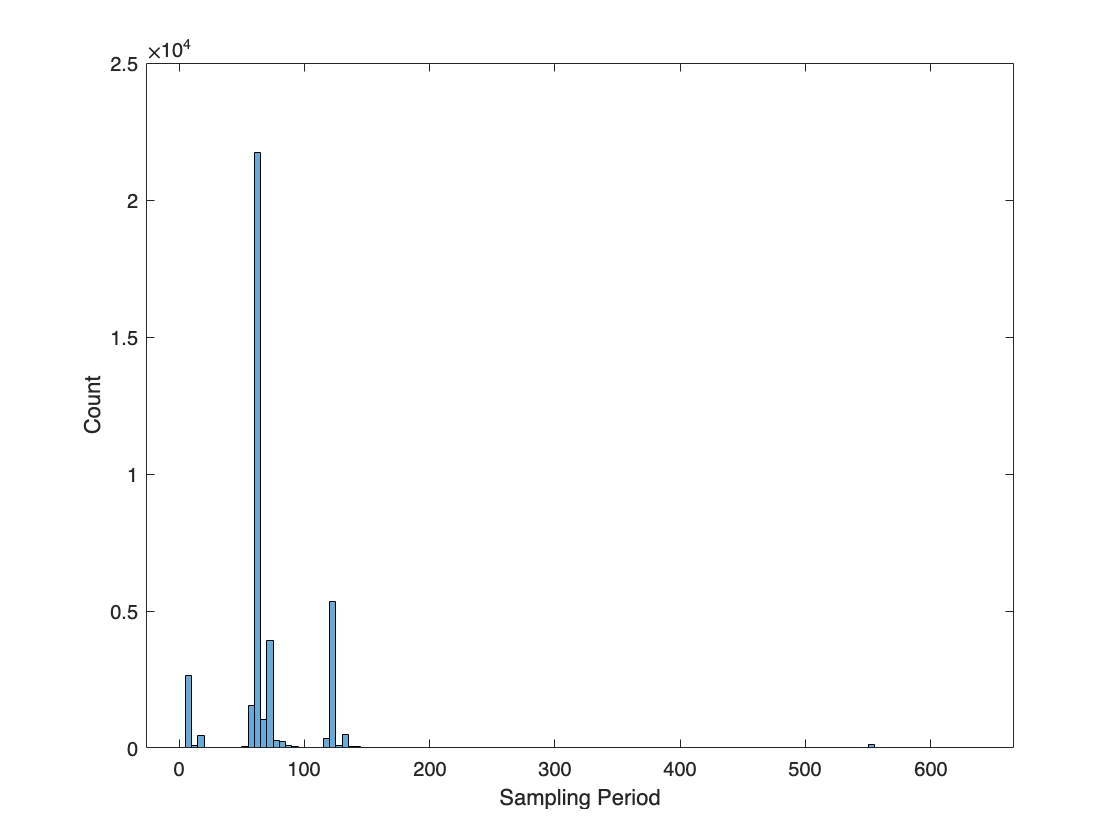

histogram(diff(Tiempo))
xlabel("Sampling Period") %Tiempo de muestreo (Ts) en ms(cada cuantos ms tomo una muestra)
ylabel("Count")

Estudio exploratorio: tratar entender que pasa a traves de graficas

Ruta de conducción


% Ts tipico es 60 (ver histograma celda anterior)
%normalizamos para Ts = 60
%resample recibe Fs en vez de Ts. Pero sabemos que Fs = 1/Ts
% usamos interpolaciòn lineal (se puede usar otras formas pero el cambio es
% minimo)
Ts = 60;
remuestreo = @(y) resample(y, Tiempo, 1/Ts, 'linear');
kmph2mps = @(x) x/3.6; % conversion km/h a m/s
mps2kmph = @(x) x*3.6; % conversion m/s a km/h

[VSSf, Tiempo] = remuestreo(kmph2mps(VSSf)); % vel km/h, Tiempo ms,
[MAPf, Tiempo] = remuestreo(MAPf);
[IAT, Tiempo] = remuestreo(IAT);
[RPMSf, Tiempo] = remuestreo(RPMSf);
[TPSf, Tiempo] = remuestreo(TPSf);
[ECTf, Tiempo] = remuestreo(ECTf);
[O2f, Tiempo] = remuestreo(O2f);

VSSf(VSSf<0)=0; % elimino vel negativas que salen del resampling

Tiempo = Tiempo/1000;

Tf = Tiempo;

Velocidades de conducciòn

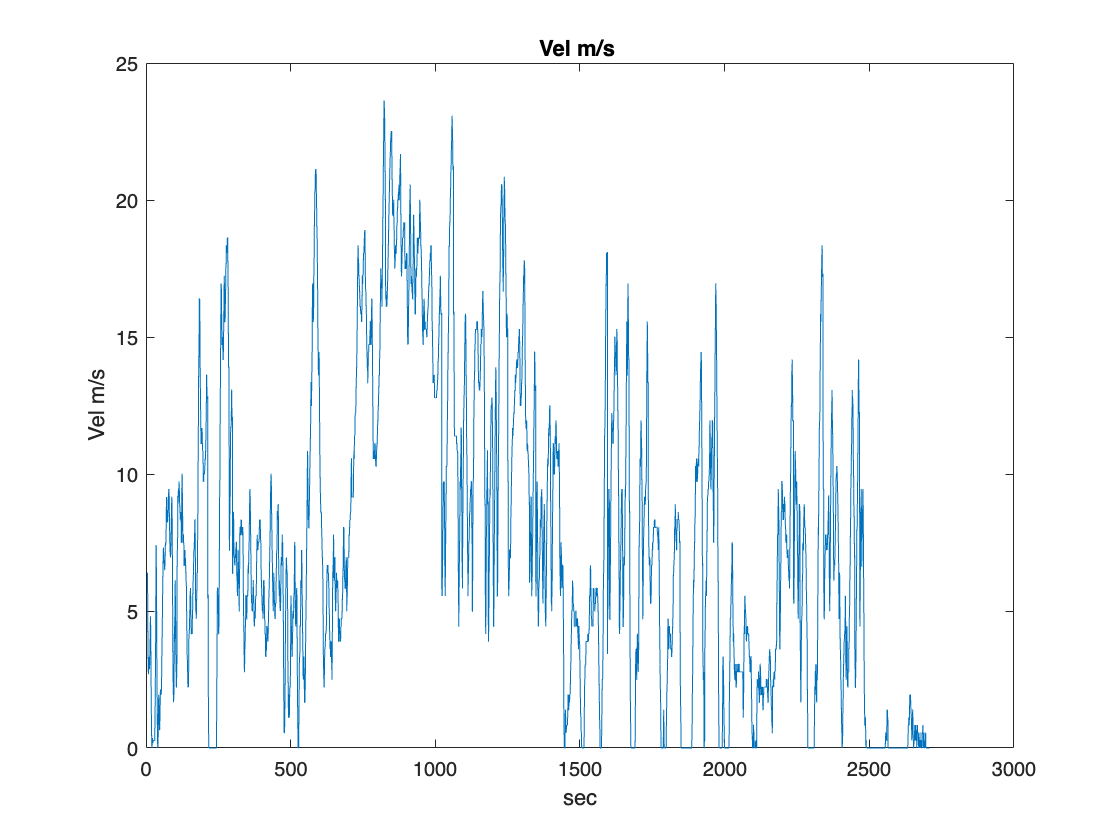

figure()
plot(Tiempo,VSSf)
xlabel("sec")
ylabel("Vel m/s")
title ("Vel m/s ")


$$a = \frac{dv}{dt}$$


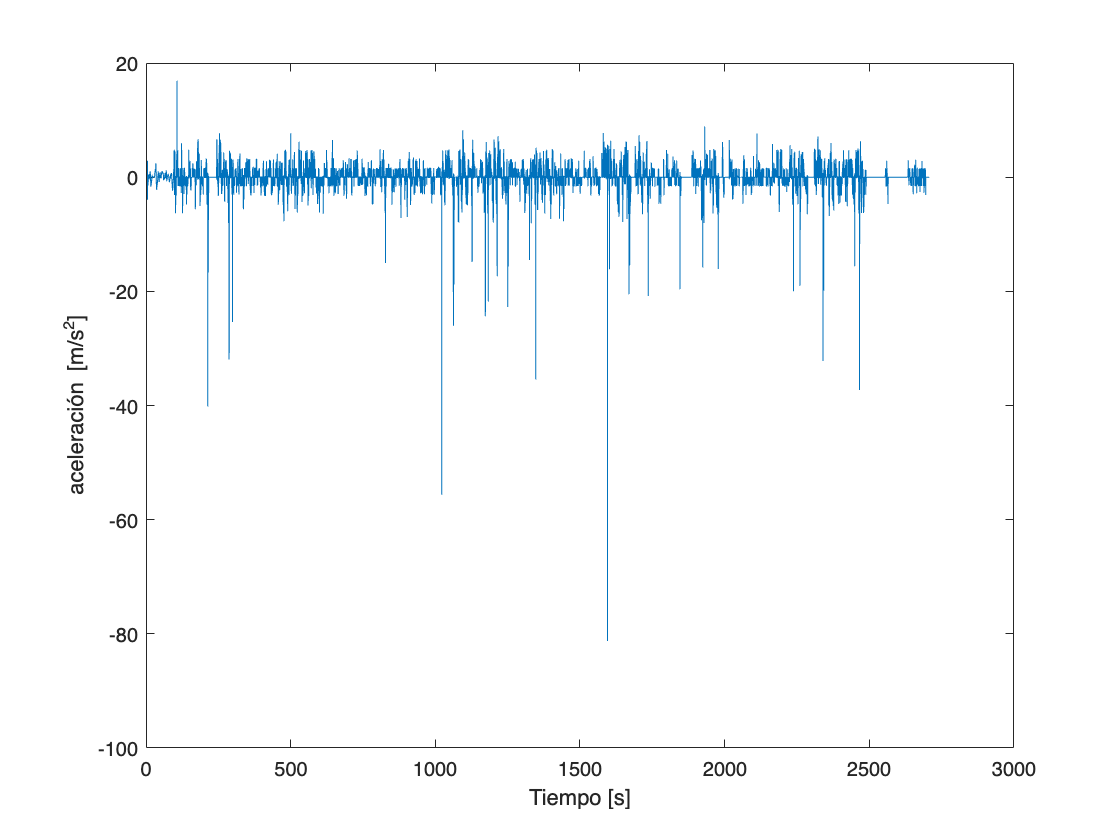

aceleracion=diff(VSSf)./diff(Tiempo);
aceleracion =[0;aceleracion];
aceleracion = sgolayfilt(aceleracion,1,3);
figure()
plot(Tiempo,aceleracion)
xlabel('Tiempo [s]')
ylabel('aceleración [m/s^2]')

Analisis de correlacion

ANOVA

Entradas van los sensores(vss,tps,rps,velocidad,acelracion)

salida: consumo de combustible

complementar correlacion de pearson

Calculo del consumo de combustible

P_1 = sgolayfilt(MAPf,1,31); %kPa
Vd = 1590; %cm^3;
R = 8.3146; %cm^3·MPa/K·mol;
temperatura = IAT+273; %K
n = (P_1.*Vd)./(1000*R*(temperatura)); %mol
Mair = 28.97; %g/mol
rev = sgolayfilt(RPMSf,1,51);
m_air= (n.*Mair.*rev)/(2*60); %g/s giro del motor
AFR = 14.7;
dens_comb = 737; %g/L
Vdm = Vd/1e6;
R_air = R/Mair; %kJ/kg·K
%dens_aire = MAP1./(R_air.*temperatura) %kg/m^3
den_air_2 = 1.181;%kg/m^3
%ve = dens_aire/den_air_2
flujo_comb = (m_air)./(AFR.*dens_comb); %L/s 
flujo_comb(isinf(flujo_comb)|isnan(flujo_comb)) = 0;
flujohr = flujo_comb*3.6e3; %l/hr
con_100k= (flujohr.*100)./VSSf; %l/100 km %%%%%VSSf tiene valores negativos, posiblemnete errores de sensamiento
con_100k(isinf(con_100k)|isnan(con_100k)) = 0; %%%%hay valores grandes, casi inf por velociades en cero. ELIMINAR OUTLIERS. hay negativos por la velocidad. eliminar outlier con percentile 95, descartar negativos.
consumo_total = (trapz(Tf/1000,flujo_comb)); %L


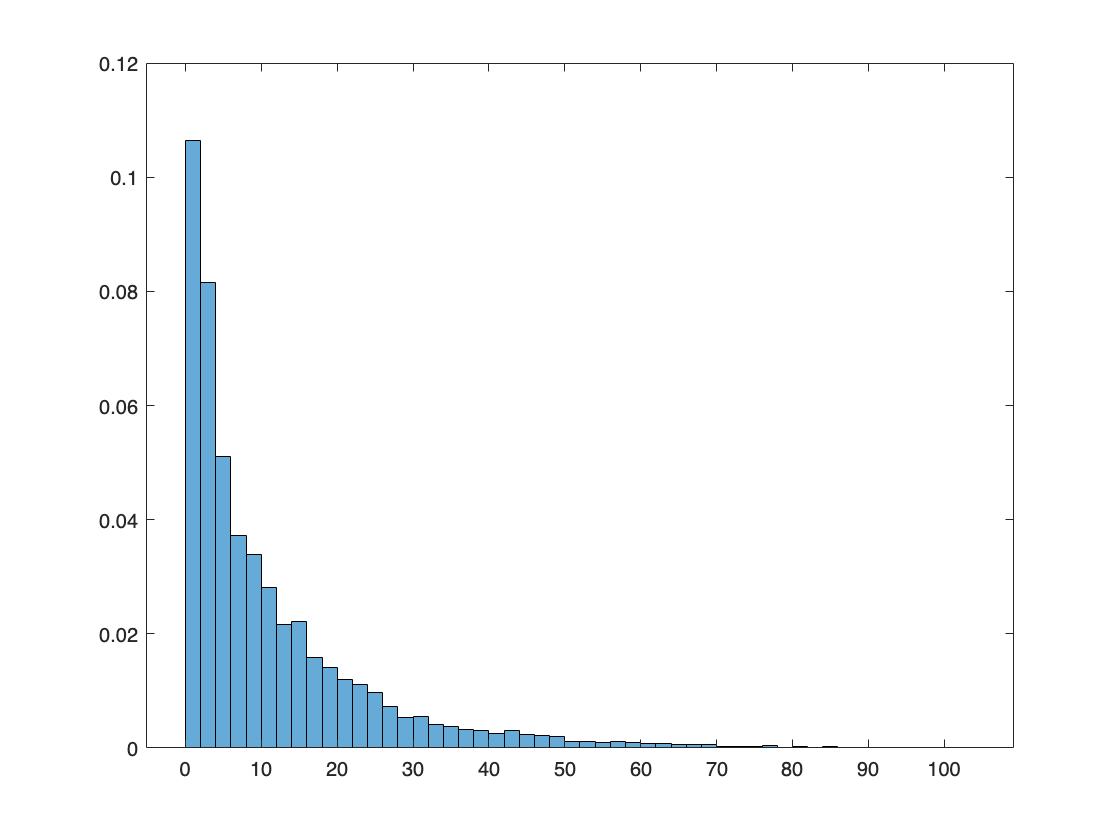


VA = calculateVA(aceleracion, VSSf, 0.1); %incluye valores de cero que deben evenutalmente retirarse del anialis
histogram(VA(VA~=0), 'Normalization','pdf') 

% excluyo valores menores al umbral de VA


%Matriz de correlación
if (GRAFICAR == true)
    Xent=table(VSSf,TPSf,RPMSf,MAPf,flujohr, aceleracion, VA);
    figure,[R,PValue] = corrplot(Xent),ax=gca;
end



% agresiveness features
RPA = calculateRPA(aceleracion, VSSf, dist_r, 0); % m/s2

RPA = 5.9178

VA95percentile = prctile(VA(VA~=0), 95); % m2/s3 excluyo valores menores al umbral de VA ????????????? leer paper

VA95percentile = 38.4950

RCS = calculateRCS(VSSf, dist_r) ;%m2/s3

RCS = 2.8523e+03

consumo_total = 0.0028

consumo_total;


% repetir get_stati... para todas variables del corrplot
% statistical features VSSf,TPSf,RPMSf,MAPf,flujohr, aceleracion, VA
[VSSf_media, VSSf_std,  VSSf_sk] = get_statistical_features(VSSf);

VSSf_media = 7.5432

VSSf_std = 5.7167

VSSf_sk = 0.5198

[TPSf_media, TPSf_std,  TPSf_sk] = get_statistical_features(TPSf);

TPSf_media = 29.2142

TPSf_std = 24.8327

TPSf_sk = 1.5223

[RPMSf_media, RPMSf_std,  RPMSf_sk] = get_statistical_features(RPMSf);

RPMSf_media = 1.8093e+03

RPMSf_std = 814.4287

RPMSf_sk = 0.4051

[MAPf_media, MAPf_std,  MAPf_sk] = get_statistical_features(MAPf);

MAPf_media = 39.2377

MAPf_std = 21.6568

MAPf_sk = 0.5540

[flujohr_media, flujohr_std,  flujohr_sk] = get_statistical_features(flujohr);

flujohr_media = 3.7112

flujohr_std = 2.8961

flujohr_sk = 1.1028

[aceleracion_media, aceleracion_std,  aceleracion_sk] = get_statistical_features(aceleracion);

aceleracion_media = -0.0023

aceleracion_std = 1.6091

aceleracion_sk = -11.4459

[VA_media, VA_std, VA_sk] = get_statistical_features(VA);

VA_media = 2.5525

VA_std = 7.7668

VA_sk = 4.7170

function rpa = calculateRPA(acc, vel, dist, threshold)
   % threshold = 0 segun https://web.archive.org/web/20200505111314id_/https://eprints.qut.edu.au/127594/1/127594.pdf

    % Subtract baseline from acceleration data
    relativeAcc = acc - threshold; %m/s2
    
    Vel_times_RelativeAcc = relativeAcc.*vel; %m2/s3

    % Set negative values to zero
    Vel_times_RelativeAcc(relativeAcc <= 0) = 0;
    
    % Calculate the sum of positive changes in acceleration
    rpa = sum(Vel_times_RelativeAcc)/dist;%m/s3
end

function va = calculateVA(acc, vel, threshold)
    % threshold = 0.1 segun https://web.archive.org/web/20200505111314id_/https://eprints.qut.edu.au/127594/1/127594.pdf
    % m2/s3
    va = vel.*acc; 
    va(acc<=threshold) = 0; %m2/s3
end

function rcs = calculateRCS(vel, dist)
    % https://web.archive.org/web/20200505111314id_/https://eprints.qut.edu.au/127594/1/127594.pdf
    rcs = sum(vel.^3)/dist;
end

function [xmean, xstd, xsk] = get_statistical_features(x)
    xmean = mean(x);
    xstd = std(x);
    xsk = skewness(x);
end
function relativePosAcc = calcularRelativePosAceleracion(accelerationData)
    % Calcula la aceleración promedio
    meanAcc = mean(accelerationData);

    % Calcula la diferencia entre la aceleración actual y la aceleración promedio
    relativePosAcc = accelerationData - meanAcc;
    relativePosAcc(relativePosAcc < 0) = 0; % Establece los valores negativos a cero
end
